clc;clear;close all

a = [1000,875,800,725,675,650,600,550,525,500];

b = 500:25:1000;
[X,Y] = meshgrid(b, a);

Z = zeros('like',X);
for i = 1:length(a)
    matName = strcat('n_Model_parameters_', num2str(a(i)), '.mat');
    load(matName)
    for j = 1:length(b)
        Z(i, j) = Model_parameters(j, 3);
    end
end

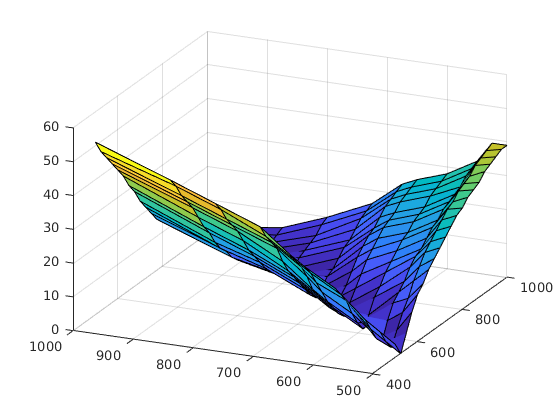

surf(X, Y, Z)